# 2D Directional Coupler

**Directional coupler** is an optical device that transfers light between two closely spaced waveguides through evanescent coupling. It is commonly used for splitting or combining signals in photonic circuits, with applications in multiplexing, modulation, and switching.

In this example, we demonstrate the scattering field of a **2D directional coupler**. Wave is injected towards and propagates along the $+x$ direction. The relative permittivity is uniform along $z$ direction, i.e.,  $\varepsilon_r=\varepsilon_r(x,y)$. All materials in the simulation are assumed to be linear, homogeneous, and isotropic (LHI).

### Step 0: Model initialization & Global settings

The simulation begins with the initialization of a `Model2D` instance, followed by defining the global settings. The working plane is set to the $\mathit{\mathbf{x}}-\mathit{\mathbf{y}}$** plane** (as default), which specifies the 2D cross-sectional area for analysis. 

modelDC = Model2D.initialize();

Model2D: Object Initialized


The core waveguides are made of **silicon (Si)** while the surrounding cladding is made of **silicon dioxide (SiO₂)**. At a wavelength of $1.55 \mu{\rm m}$ (the operating wavelength), the refractive indices are $n_{\rm Si} = 3.4712$ and $n_{\rm SiO_2} = 1.4434$.

eps_Si = 3.4712^2; % Silicon (waveguide)
eps_SiO2 = 1.4434^2; % Silicon dioxide (background)
modelDC.setBackground('eps_r',eps_SiO2);

### Step 1: SImulation device

This step constructs the simulation domain by specifying the geometry and material properties of the silicon waveguides. Using the `Model2D` class, each device component is seamlessly created and configured, enabling an accurate representation of the directional coupler's physical structure.

#### 1.1 Geometry parameters

The width of each waveguide is $0.48 \mu{\rm  m}$, with a gap of $0.2 \mu{\rm m}$ between them. One waveguide has a length of $80 \mu{\rm m}$, while the other one is $5 \mu{\rm m}$ shorter, providing an offset for the injection source. The total dimensions of the silicon dioxide cladding are $80 \mu{\rm m}$ in length and $3 \mu{\rm m}$ in width.

% geometry parameters [unit: m]
L = 80e-6; % total length
W = 3e-6; % total width
L_wg = 80e-6; % length of wavegudie
L_offset = 5e-6; % offset length
W_wg = 0.48e-6; % width of waveguide
W_gap = 0.2e-6; % width of gap

#### 1.2 Si straight waveguides

The two silicon waveguides form the core components of the directional coupler. They enable the transfer of optical power through evanescent coupling, where light from one waveguide interacts with the other due to their close proximity. The asymmetry introduced by the offset in one waveguide helps to control the direction of injected source.

% Long waveguide
modelDC.addDevice(1);
modelDC.setDevice(1).setGeometry('Rectangle', L_wg, W_wg, 'bl', [0, W_gap/2]);
modelDC.setDevice(1).setMaterial(eps_Si);

% Short waveguide
modelDC.addDevice(2);
modelDC.setDevice(2).setGeometry('Rectangle', L_wg-L_offset, W_wg, 'tl', [L_offset, -W_gap/2]);
modelDC.setDevice(2).setMaterial(eps_Si);

#### 1.3 Complete device building

Once the components are added, the device-building process is finalized using `model.assembleDevice`. The `dispImg` method is called to visually confirm the constructed geometry.

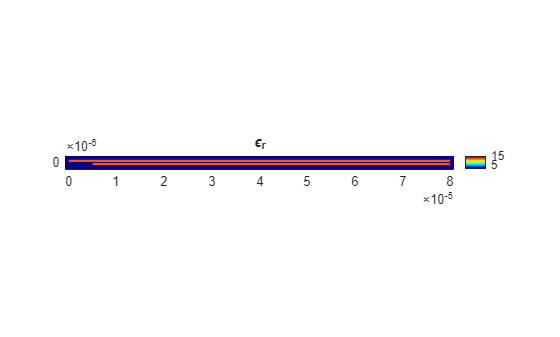

modelDC.assembleDevice;
modelDC.device.dispImg;

### Step 2: FDFD region mesh grid

The FDFD solver operates on a uniform mesh grid to discretize the simulation domain. Before meshing, the geometry is represented as a `polyshape` object. After meshing, it transforms into a discrete double array that captures the spatial distribution of relative permittivity $\varepsilon_r$ and relative permeability $\mu_r$.

The FDFD region is set in the $x-y$ plane, matching the silicon dioxide cladding box, with grid sizes of approximately ${\rm d}x \approx 44.42 {\rm nm}$ and ${\rm d}y \approx 14.92 {\rm nm}$. 

% mesh grid
Nx = 1801; dx = L/Nx;
Ny = 201;  dy = W/Ny;
modelDC.setMesh([Nx, Ny], [dx, dy]);
modelDC.shiftMesh('x', 'c', L/2);

% mesh device
modelDC.meshDevice;

### Step 3: Configure FDFD solver

#### 3.1 Set wavelength

The operating wavelength is defined when configuring the FDFD solver. The simulation operates at a wavelength of **1.55 µm**, commonly used in optical communications. 

modelDC.setWavelength(1.55e-6); % model works at 1.55 um

#### 3.2 Choose correct solver

We are going to solve a scattering problem. Therefore, we need to choose `'Scattering' `solver here.

modelDC.setSolver("Scattering", 'TE');

#### 3.3 Set PML boundary condition

A crucial aspect of the setup involves defining **Perfectly Matched Layers (PML)** around the device. These layers absorb outgoing waves and prevent reflections at the boundaries, ensuring accurate simulation results. The thickness of the PML (defined as the number of grid pixels) must be carefully chosen—it should be sufficient to absorb waves effectively but not so thick that it interferes with the device region or reduces the free space available for wave propagation.

modelDC.setBoundary('x', 'PML', 50);
modelDC.setBoundary('y', 'PML', 20);

### Step 4: Set port

The port must be defined inside the FDFD region. As mentioned earlier, the input wave propagates along the $+x$ direction. The port is located at $x=3 \mu{\rm m}$ and spans from $y=-1 \mu{\rm m}$ to $y=1 \mu{\rm m}$, covering only the cross-section of the longer waveguide.

modelDC.addPort('+x', 3e-6, [-1e-6, 1e-6]); % unit: m

### Step 5: Configure input source

The input wave is configured to use the **fundamental transverse electric (TE) eigenmode** of the waveguide. This mode is selected due to its compatibility with the geometry and operating wavelength, ensuring efficient coupling and propagation.

- **Polarization**: TE (Transverse Electric) mode.

- **Mode Number**: Fundamental mode.

The `setSource` method configures the input source, and the resulting field distribution $|E_z|$ is visualized to confirm the setup.

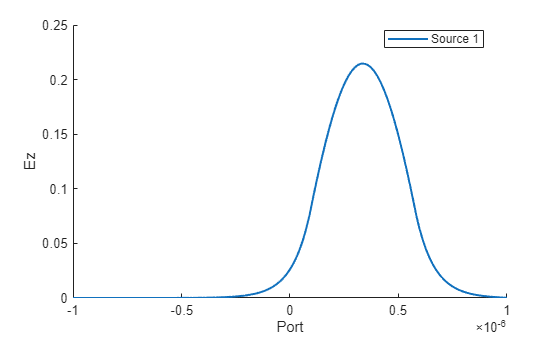

num_mode = 1; % fundamental mode
modelDC.addSource("EigenMode", num_mode);
modelDC.cfg.source.dispProfile('Ez');

### Step 6: 2D scattering simulation

To simulate the scattering behavior of the directional coupler, the device must be fully meshed, and the input source properly configured. 

modelDC.dispInfo; % comfirm settings before launching solver

=== Model2D Information ===
Wavelength   : 1.550e-06 m
Plane Label  : xy
Background   : eps_r=2.083, mu_r=1.000
Mesh         : x: N=1801, d=4.442e-08 m
               y: N=201, d=1.493e-08 m
Solver       : Scattering
BC (x)     : PML, thickness=50
BC (y)     : PML, thickness=20
Source Polarization : TE
Source Port         : dir=+x
                      position (x) = 3.000e-06 m
                      span (y)     = [-1.000e-06, 1.000e-06] m


modelDC.solveModel;

Model object has been solved successfully.


results = modelDC.exportResults;

When the solving is completed, we can export and visulize simulation results.

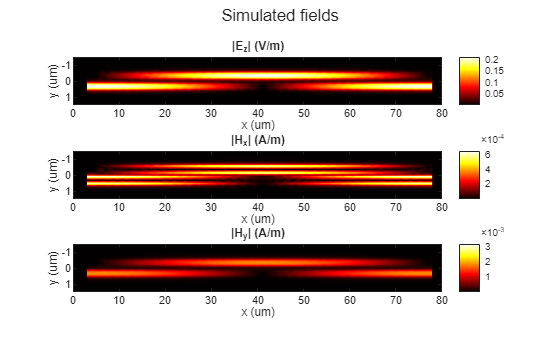

figure; sgtitle('Simulated fields')
subplot(3,1,1);
imagesc(results.x*1e6, results.y*1e6, abs(results.Ez).');
xlabel('x (um)'), ylabel('y (um)'); 
title('|E_z| (V/m)');
colormap hot; colorbar;
subplot(3,1,2);
imagesc(results.x*1e6, results.y*1e6, abs(results.Hx).');
xlabel('x (um)'), ylabel('y (um)');
title('|H_x| (A/m)');
colormap hot; colorbar;
subplot(3,1,3);
imagesc(results.x*1e6, results.y*1e6, abs(results.Hy).');
xlabel('x (um)'), ylabel('y (um)');
title('|H_y| (A/m)');
colormap hot; colorbar;

As expected, light is coupled while propagating in two waveguides.